## 3. An example - a lipid monolayer.

In the next chapter, we'll look in detail how to set up the problem definition for a given situation. Initially though, it's useful to take a pre-prepared problem definition, and to see how this is then used in RAT. As an example, we'll use some neutron reflectivity data for a lipid monolayer, collected at various deuterations, which we want to analyse simultaneously.

In terms of reflectivity, the interface we want to model (i.e. a monolayer at an air-water interface) is usually well modeled by two layers: the hydrophobic tail regions of the lipids, which locate outside the bulk water interface, and the hydrophilic heads wich are adjacent (or embedded) in the bulk aqueous phase. 

In our example, the layers can be either deuterated of hydrogenated, and the bulk water can either be D2O or ACMW.

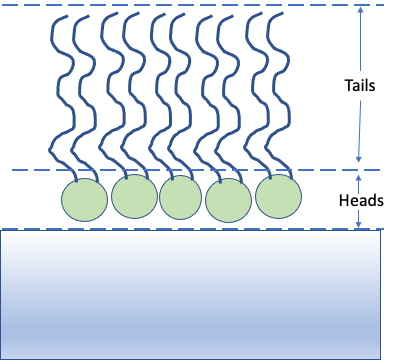

The way this kind of model is set up for RAT should be familliar to anyone who has used RasCAL, in that we identify which parameters we need to describe the model, group these into layers, and then group the layers along with data into contrasts. The advantage pf this approach is that it's simple to share parameters beytween layers, so a layer representing deuterated headgroups should share the same thickness and roughness parameters as a layer representing hydrogenated heads, but they should differ from each other in their SLD. 

The problem definition in RAT is done by making an instance of a problemDef class, and then using the class methods to then set the layers and so on. But for now, we'll look at a pre-prepared example.

% Load in a pre-made problemDef class
problem = load('twoContrastExample.mat');
problem = problem.problem;

% Have a look at what we have
disp(problem)

         ModelType: 'Standard Layers'
    experimentName: 'DSPC monolayers'
          Geometry: 'air/substrate'

    Parameters: ---------------------------------------------------------------------------------------------- 

    p               Name               Min       Value      Max     Fit? 
    __    ________________________    ______    _______    _____    _____

     1    "Substrate Roughness"            2          3       13    true 
     2    "Tails Thickness"               10         20       30    true 
     3    "Heads Thickness"                3         11       16    true 
     4    "Tails Roughness"                2          5        9    true 
     5    "Heads Roughness"                2          5        9    true 
     6    "Deuterated Tails SLD"       4e-06      6

% Make an instance of a projectClass:
problem = projectClass('test');

% Check what type our class is...
class(problem)

ans = 'projectClass'


% Have a look at its class methods..
methods(problem)

Methods for class projectClass:

addBackground       addLayerGroup       removeData          setBulkIn           setModelType        setUsePriors        
addBacksPar         addParam            removeParam         setBulkOut          setParamConstr      toStruct            
addBulkIn           addParamGroup       setBackgroundName   setContrast         setParamFit         
addBulkOut          addQzshift          setBackgroundValue  setContrastModel    setParamName        
addContrast         addScalefactor      setBacksPar         setCustomFile       setParamPrior       
addCustomFile       getAllAllowedNames  setBacksParConstr   setData             setParamValue       
addData             projectClass        setBacksParName     setGeometry         setParameter        
addLayer            removeBacksPar      setBacksParValue    setLayerValue       setScalefactor      

Methods of projectClass inherited from <a href="matlab:helpPopup handle">handle</


% Check our empty project class:
disp(problem)

         ModelType: 'Standard Layers'
    experimentName: 'test'
          Geometry: 'air/substrate'

    Parameters: ---------------------------------------------------------------------------------------------- 

    p            Name             Min    Value    Max    Fit? 
    _    _____________________    ___    _____    ___    _____

    1    "Substrate Roughness"     1       3       5     true 

    Layers: -------------------------------------------------------------------------------------------------- 

    Name    Thickness    SLD    Roughness    Hydration    Hydrate with
    ____    _________    ___    _________

% Make an instance of the controlsDef class
controls = controlsDef();

disp(controls)

  controlsDef with properties:

            parallel: 'single'
           procedure: 'calculate'
    calcSldDuringFit: 'no'



% Send the details to RAT

[outProblem,results] = RAT(problem,controls)

Unrecognized function or variable 'layersDetails'.

Error in projectClass/toStruct (line 689)
                    layersStruct.layersDetails = layersDetails(:);

Error in RatParseClassToStructs_new (line 67)
inputStruct = inputProblemDef.toStruct();

Error in 